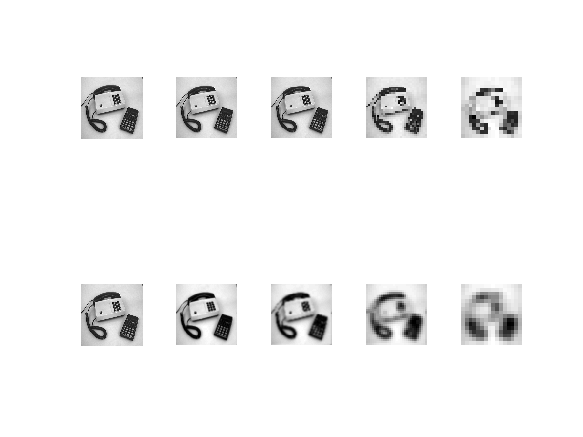

img = phonecalc256;
     smoothimg = img;
     N=5;
     for i=1:N
       if i>1    % generate subsampled versions
         % first sample, the smooth, gives better result
         img = rawsubsample(img);
         smoothimg = gaussfft(img, 0.7); %  gaussian
         %smoothimg = ideal(img, 0.7); % ideal lowpass
         
         
         
         % first smooth image and the sample it. becomes worse
         %smoothimg = gaussfft(img, 0.5); % gassian filter
         %smoothimg = ideal(img, 0.6); % ideal low pass
         %img = rawsubsample(smoothimg);
         
         
         
         
         %smoothimg = ideal(smoothimg, 0.5);
         %smoothimg = rawsubsample(smoothimg);
       end
       subplot(2, N, i)
       showgrey(img)
    
       subplot(2, N, i+N)
       showgrey(smoothimg)
       
     end 